** Simulation Assignment**

Question 01

L = 1000; %length of binary sequence
%generating the binary sequence
D_ord = [zeros(1,L/2),ones(1,L/2)]; %generating equiprobable ordered binary sequence
D = D_ord(randperm(length(D_ord))) %shuffle the sequence

D =      1     1     0     1     0     1     1     1     0     0     0     0     0     0     1     0     1     0     0     0     0     1     0     1     0     1     1     1     0     0     0     0     1     0     1     1     1     1     1     1     0     1     1     1     0     0     1     0     1     1


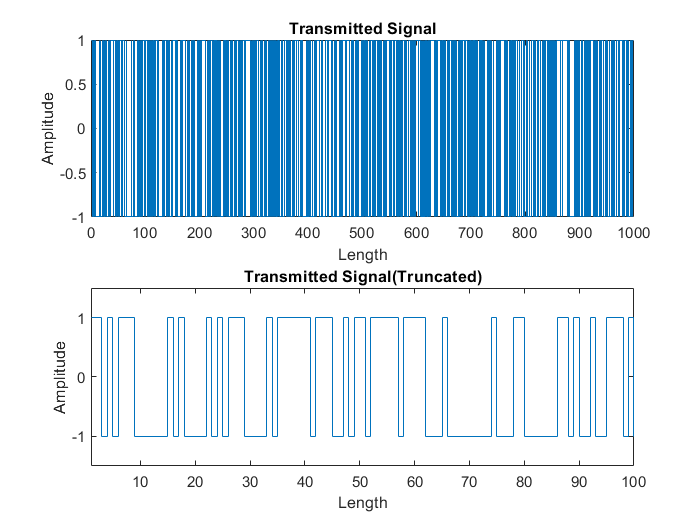

%generating the pulse stream
A =1; %amplitude
S = zeros(1,L); %generating the transmitted signal
S(D==0) = -A;
S(D==1) = A;
subplot(2,1,1);
Plot(L,S,"Transmitted Signal","Length","Amplitude")
subplot(2,1,2);
Plot(L,S,"Transmitted Signal(Truncated)","Length","Amplitude")
xlim([1 100]) %zoomed for a part
ylim([-1.5 1.5])

Question 02

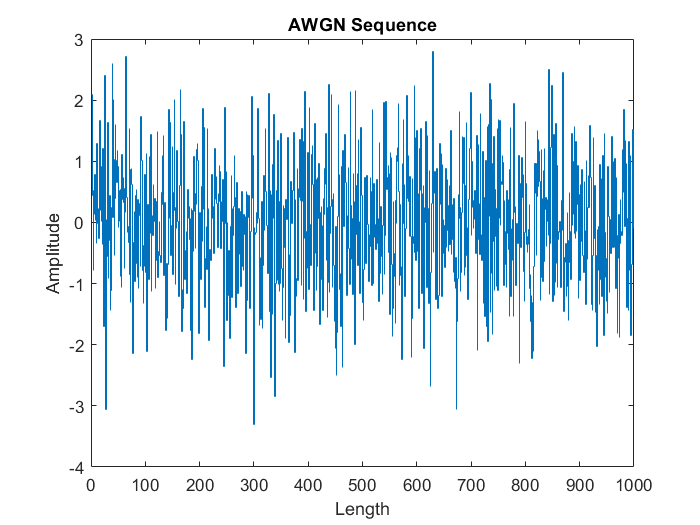

%generating an AWGN sequence
mu = 0; %mean=0
sigma = 1; %since variance=1 %change this for question 3
N = normrnd(mu,sigma,1,L); %generating noise
figure;
Plot(L,N,"AWGN Sequence","Length","Amplitude") %getting the plot

Question 03

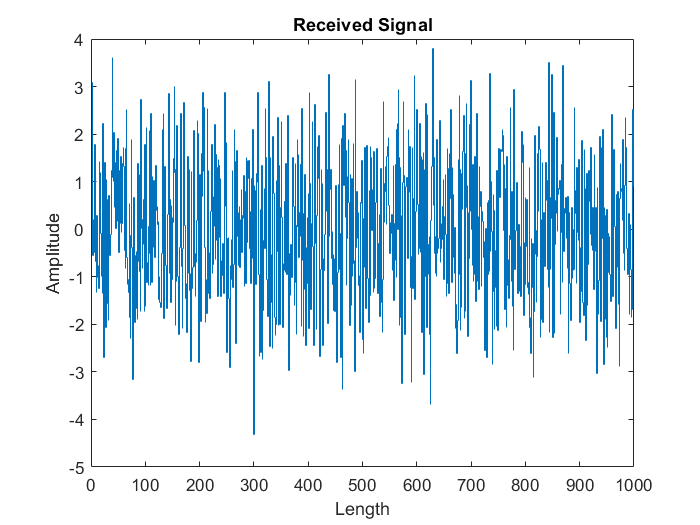

%generating the received signal
R = S + N;
%plotting the received signal
figure;
Plot(L,R,"Received Signal","Length","Amplitude")

Question 04

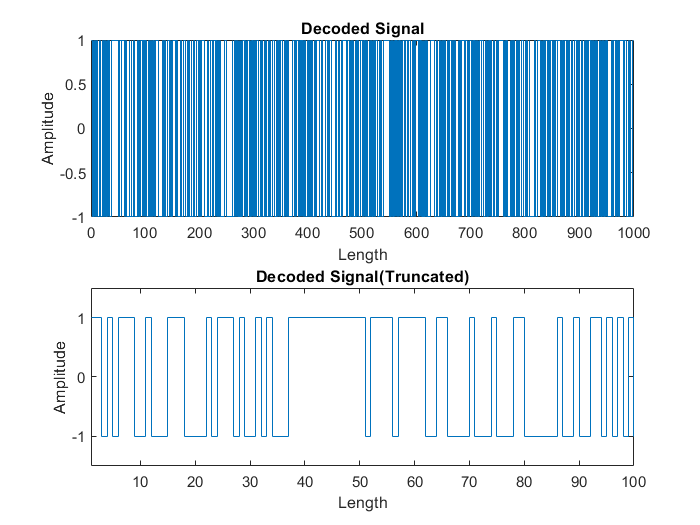

%generating the decoded sequence Y 
Y = zeros(1,L);
tau = 0; %threshold value
for len = 1:L
 if R(len) > tau
 Y(len) = A;
 else
 Y(len) = -A;
 end
end
figure;
subplot(2,1,1);
Plot(L,Y,"Decoded Signal","Length","Amplitude")
subplot(2,1,2);
Plot(L,Y,"Decoded Signal(Truncated)","Length","Amplitude")
xlim([1 100]) %zoomed for a part
ylim([-1.5 1.5])

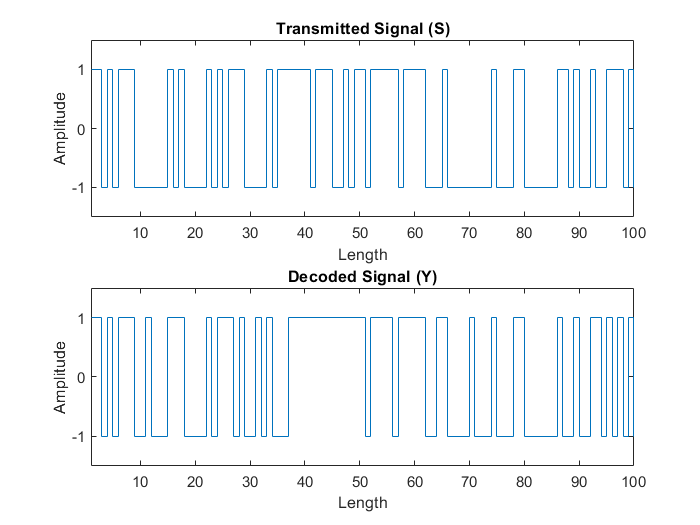

%comparing truncated versions
figure;
subplot(2,1,1);
Plot(L,S,"Transmitted Signal (S)","Length","Amplitude")
xlim([1 100])
ylim([-1.5 1.5])
subplot(2,1,2);
Plot(L,Y,"Decoded Signal (Y)","Length","Amplitude")
xlim([1 100])
ylim([-1.5 1.5])

Question 05

L = 100000; %length of binary sequence
A = 2; %amplitude
%generating the binary sequence
D_ord = [zeros(1,L/2),ones(1,L/2)]; %generating equiprobable ordered binary sequence
D = D_ord(randperm(length(D_ord))) %shuffle the sequence

D =      1     0     0     0     0     0     0     1     0     0     0     1     1     0     1     1     1     1     1     1     0     0     1     1     1     1     1     0     1     1     1     1     0     0     0     0     0     0     1     1     1     1     0     1     1     1     1     0     0     0


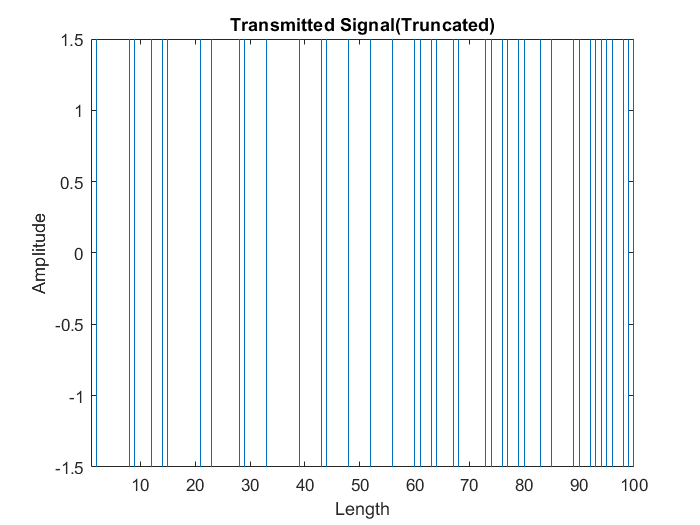


%generating the pulse stream
S = zeros(1,L); %generating the transmitted signal
S(D==0) = -A;
S(D==1) = A;
figure;
Plot(L,S,"Transmitted Signal(Truncated)","Length","Amplitude")
xlim([1 100]) %zoomed for a part
ylim([-1.5 1.5])

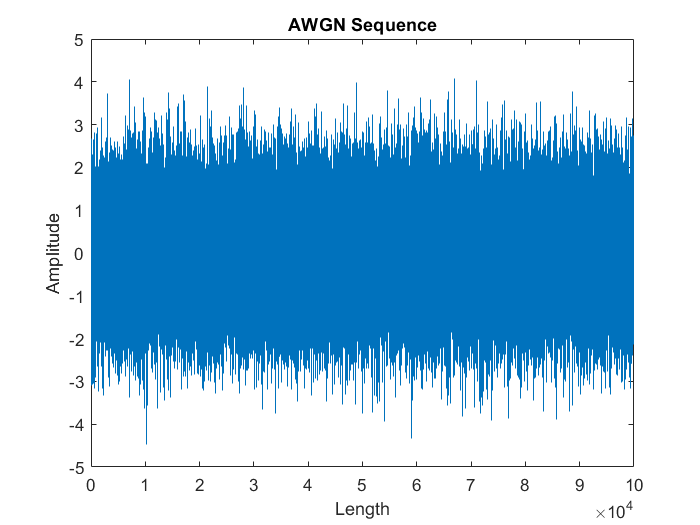


%generating an AWGN sequence
mu = 0; %mean=0
sigma = 1; %since variance=1
N = normrnd(mu,sigma,1,L); %generating noise
figure;
Plot(L,N,"AWGN Sequence","Length","Amplitude") %getting the plot

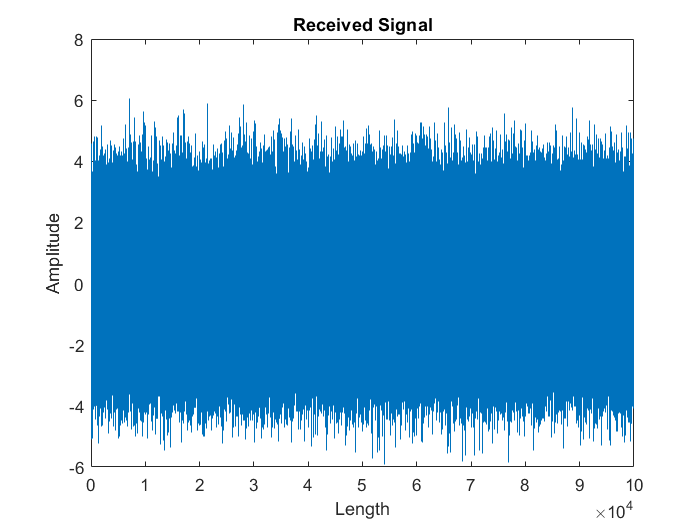


%generating the received signal
R = S + N;
figure;
Plot(L,R,"Received Signal","Length","Amplitude")

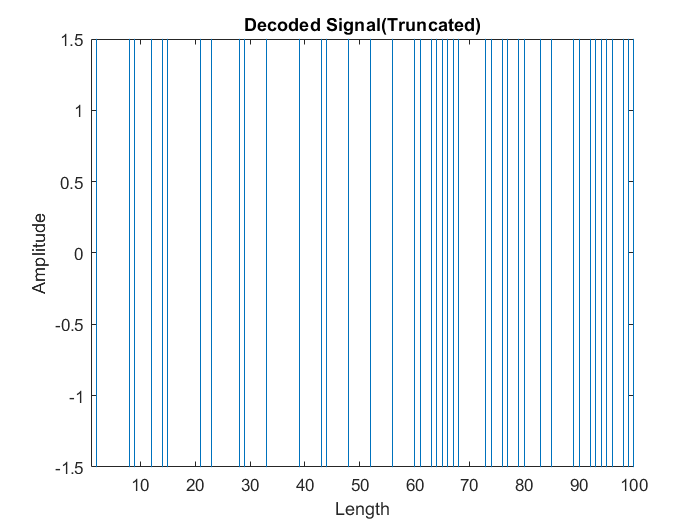


%generating the decoded sequence Y 
Y = zeros(1,L);
tau = 0; %threshold value
for len = 1:L
 if R(len) > tau
 Y(len) = A;
 else
 Y(len) = -A;
 end
end
figure;
Plot(L,Y,"Decoded Signal(Truncated)","Length","Amplitude")
xlim([1 100]) %zoomed for a part
ylim([-1.5 1.5])

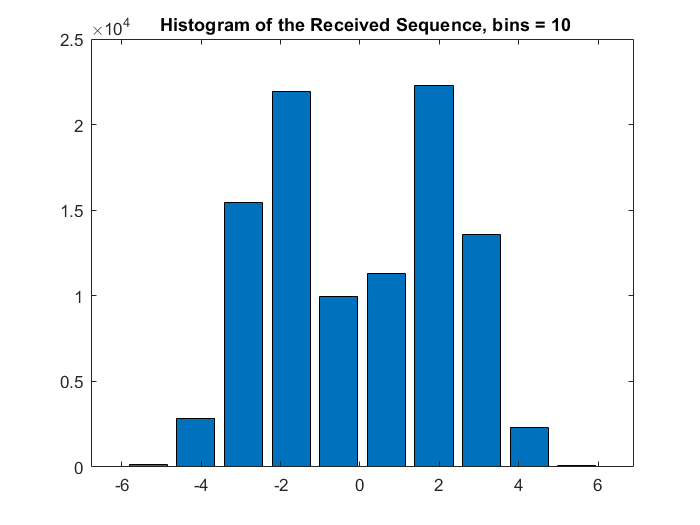

%generate and plot the histogram of the received sequence taking the no of bins as 10
[histo,bin] = myhisto(R,10); %without functions
figure;
bar(bin,histo);
title(" Histogram of the Received Sequence, bins = 10");

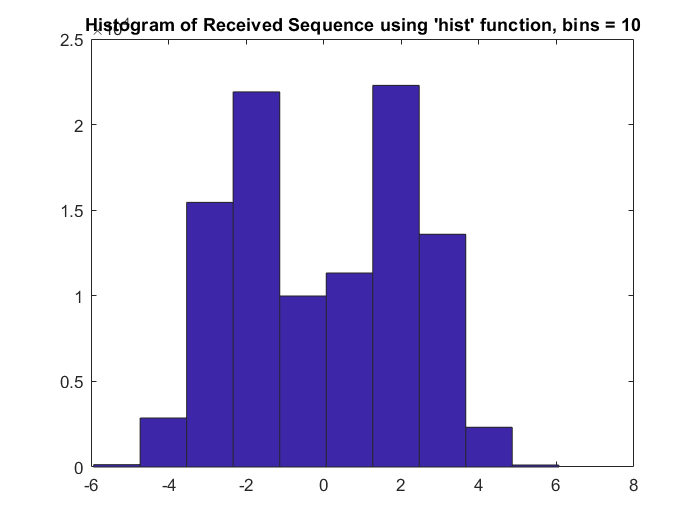

%using the buit in function hist()
figure;
hist(R,10);
title("Histogram of Received Sequence using 'hist' function, bins = 10");

Question 05 - Part (a)

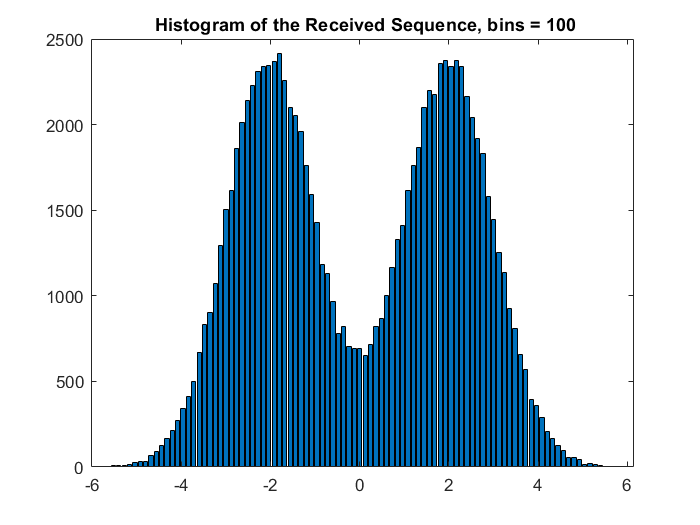

%without functions
[histo,bin] = myhisto(R,100);
figure;
bar(bin,histo);
title(" Histogram of the Received Sequence, bins = 100");

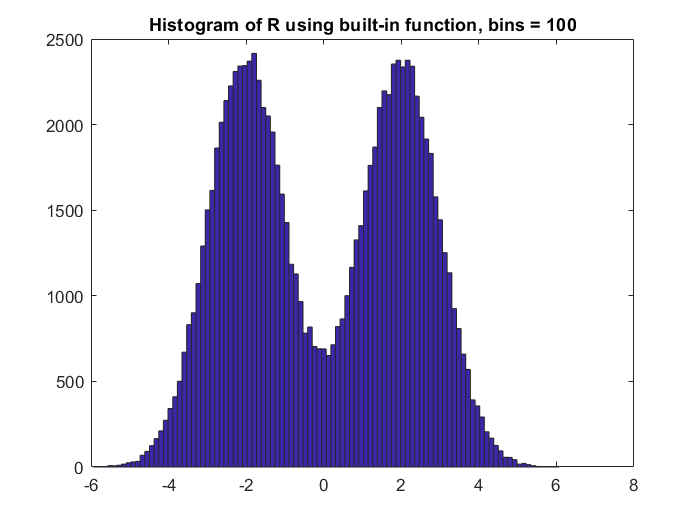

%using the buit in function hist()
nbins_new=100;
figure;
hist(R,nbins_new);
title("Histogram of R using built-in function, bins = 100");

Question 05 - Part (b)

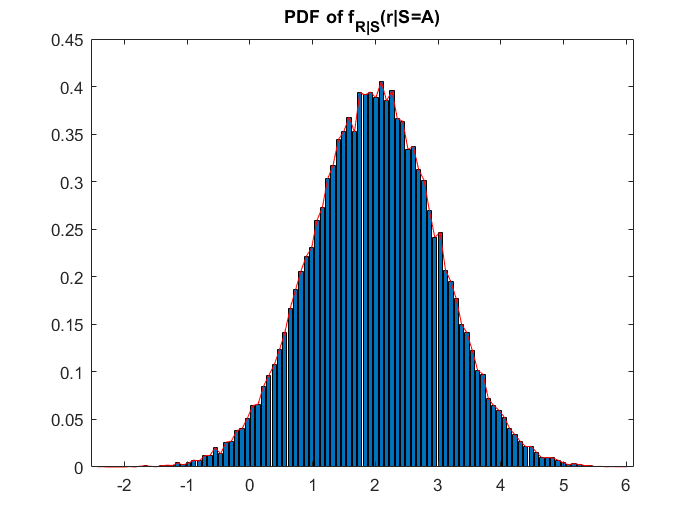

%plotting the pdf of f_R|S(r|S=A)
A=2; %change when doing 5b
[R_pdf1,R_bins1] = fRS(R,S,A);
figure;
bar(R_bins1,R_pdf1);
hold on;
plot(R_bins1,R_pdf1,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=A)");

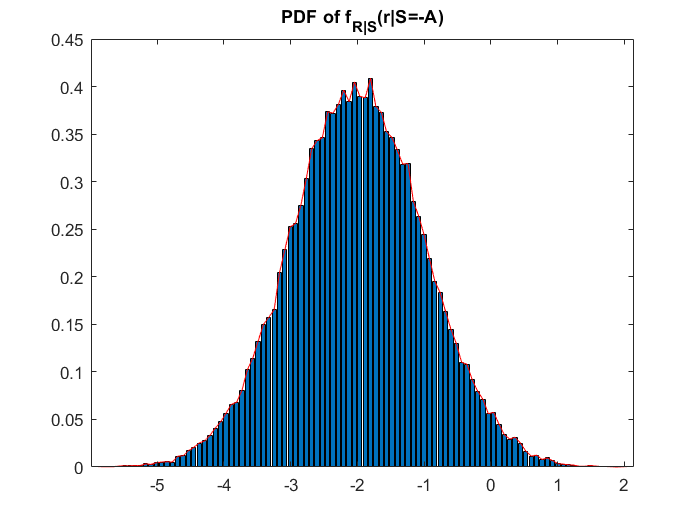

%plotting the pdf of f_R|S(r|S=-A)
[R_pdf2,R_bins2] = fRS(R,S,-A);
figure;
bar(R_bins2,R_pdf2);
hold on;
plot(R_bins2,R_pdf2,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=-A)");

Question 05 - Part (c)

%calculating E[R|S=A]
ER_SA = 0;
gap1 = R_bins1(2)-R_bins1(1);
for cnt1 = 1:100
 ER_SA = ER_SA + (R_bins1(cnt1)*R_pdf1(cnt1)*gap1);
end
ER_SA

ER_SA = 1.9959

%calculating E[R|S=-A]
ER_SnA = 0;
gap2 = R_bins2(2)-R_bins2(1);
for cnt2 = 1:100
 ER_SnA = ER_SnA + (R_bins2(cnt2)*R_pdf2(cnt2)*gap2);
end
ER_SnA

ER_SnA = -1.9931

%calculating E[R]
[y,x] = hist(R,100);
gap3 = x(2)-x(1);
y = y/(L*gap3);
E_R = 0;
for cnt3 = 1:100
 E_R = E_R + (x(cnt3)*y(cnt3)*gap3);
end
E_R

E_R = 0.0013

Question 05 - Part (d)

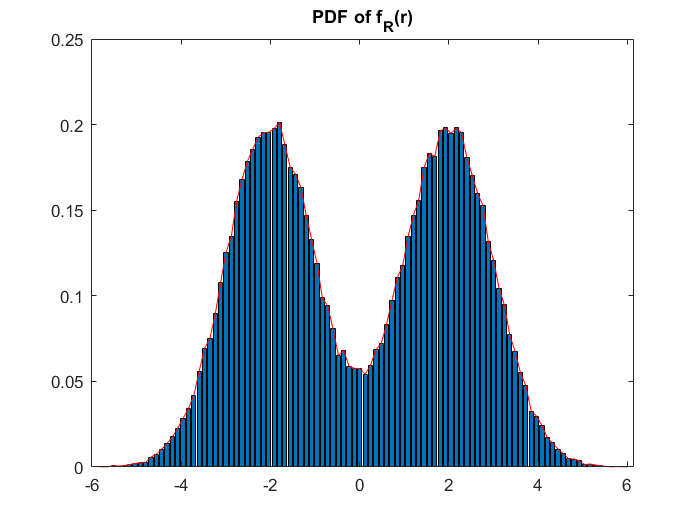

%plotting the pdf of f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF of f_R(r)");

Question 06

%generating  interference sequence
L = 100000

L = 100000

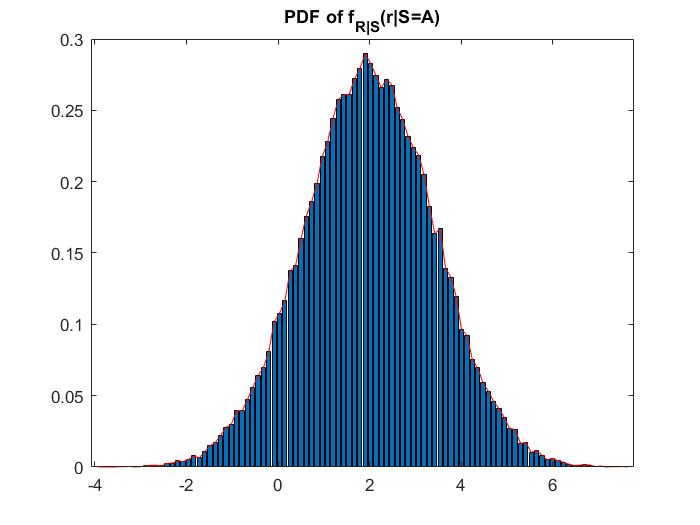

mu = 0; %mean=0
sigma = 1; %since variance=1
I = normrnd(mu,sigma,1,L); %generating  interference
%generating the received signal
R_int = S + N + I;

%5b
%plotting the pdf of f_R|S(r|S=A)
A=2; %change when doing 5b
[R_pdf1,R_bins1] = fRS(R_int,S,A);
figure;
bar(R_bins1,R_pdf1);
hold on;
plot(R_bins1,R_pdf1,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=A)");

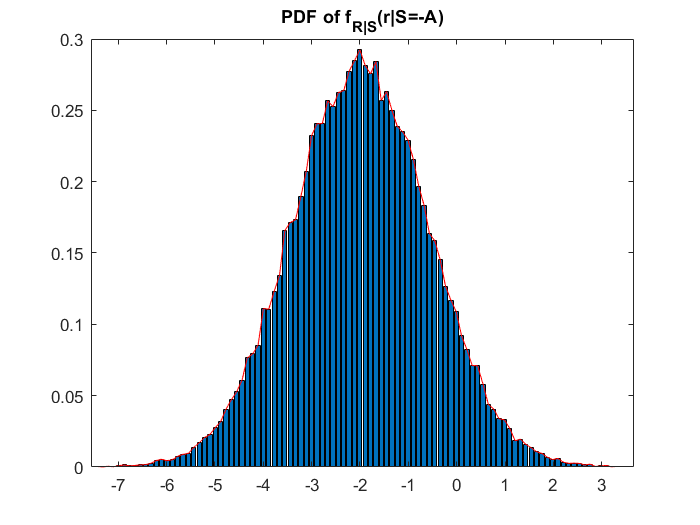

%plotting the pdf of f_R|S(r|S=-A)
[R_pdf2,R_bins2] = fRS(R_int,S,-A);
figure;
bar(R_bins2,R_pdf2);
hold on;
plot(R_bins2,R_pdf2,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=-A)");

%5c
%calculating E[R|S=A]
ER_SA = 0;
gap1 = R_bins1(2)-R_bins1(1);
for cnt1 = 1:100
 ER_SA = ER_SA + (R_bins1(cnt1)*R_pdf1(cnt1)*gap1);
end
ER_SA

ER_SA = 1.9997

%calculating E[R|S=-A]
ER_SnA = 0;
gap2 = R_bins2(2)-R_bins2(1);
for cnt2 = 1:100
 ER_SnA = ER_SnA + (R_bins2(cnt2)*R_pdf2(cnt2)*gap2);
end
ER_SnA

ER_SnA = -1.9834

%calculating E[R]
[y,x] = hist(R_int,100);
gap3 = x(2)-x(1);
y = y/(L*gap3);
E_R = 0;
for cnt3 = 1:100
 E_R = E_R + (x(cnt3)*y(cnt3)*gap3);
end
E_R

E_R = 0.0084

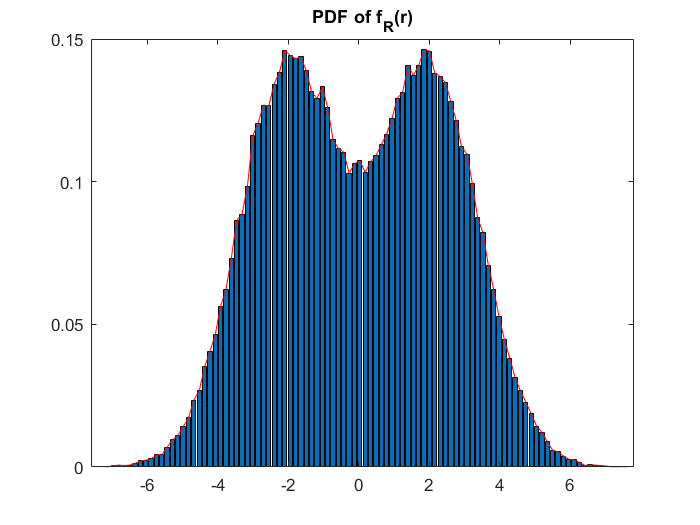

%5d
%plotting the pdf of f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF of f_R(r)");

Question 07

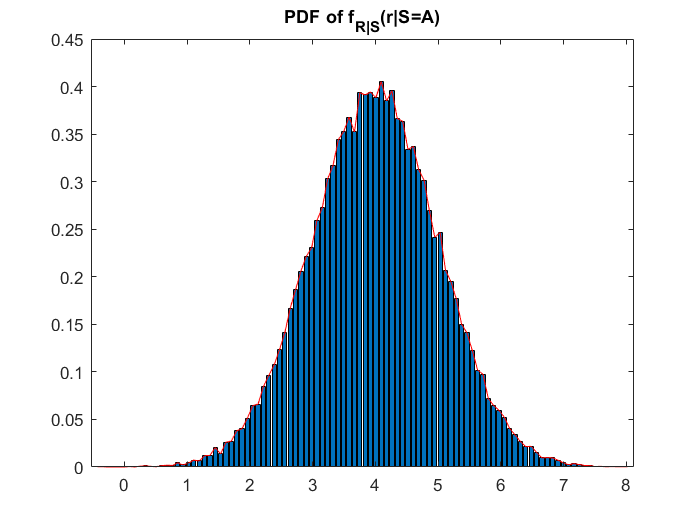

%generating the received signal
alpha = 2; %scaling factor
R_amp = alpha*S + N;

%5b
%plotting the pdf of f_R|S(r|S=A)
A=2; %change when doing 5b
[R_pdf1,R_bins1] = fRS(R_amp,S,A);
figure;
bar(R_bins1,R_pdf1);
hold on;
plot(R_bins1,R_pdf1,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=A)");

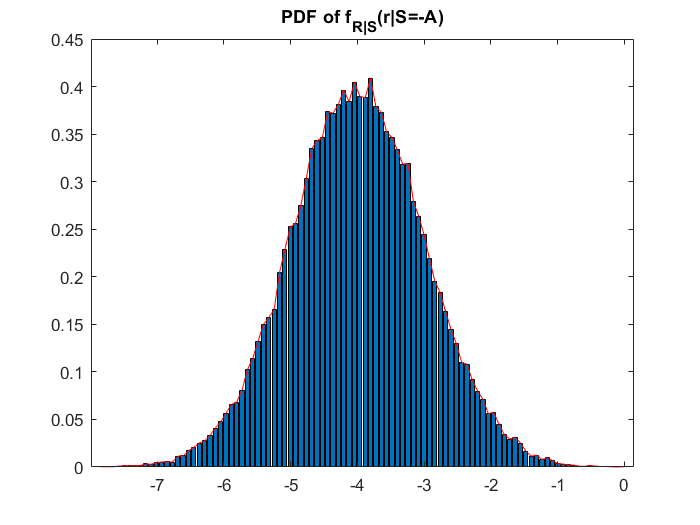

%plotting the pdf of f_R|S(r|S=-A)
[R_pdf2,R_bins2] = fRS(R_amp,S,-A);
figure;
bar(R_bins2,R_pdf2);
hold on;
plot(R_bins2,R_pdf2,'r'); %plotting the pdf for it
title("PDF of f_{R|S}(r|S=-A)");


%5c
%calculating E[R|S=A]
ER_SA = 0;
gap1 = R_bins1(2)-R_bins1(1);
for cnt1 = 1:100
 ER_SA = ER_SA + (R_bins1(cnt1)*R_pdf1(cnt1)*gap1);
end
ER_SA

ER_SA = 3.9959


%calculating E[R|S=-A]
ER_SnA = 0;
gap2 = R_bins2(2)-R_bins2(1);
for cnt2 = 1:100
 ER_SnA = ER_SnA + (R_bins2(cnt2)*R_pdf2(cnt2)*gap2);
end
ER_SnA

ER_SnA = -3.9931


%calculating E[R]
[y,x] = hist(R_amp,100);
gap3 = x(2)-x(1);
y = y/(L*gap3);
E_R = 0;
for cnt3 = 1:100
 E_R = E_R + (x(cnt3)*y(cnt3)*gap3);
end
E_R

E_R = 0.0015

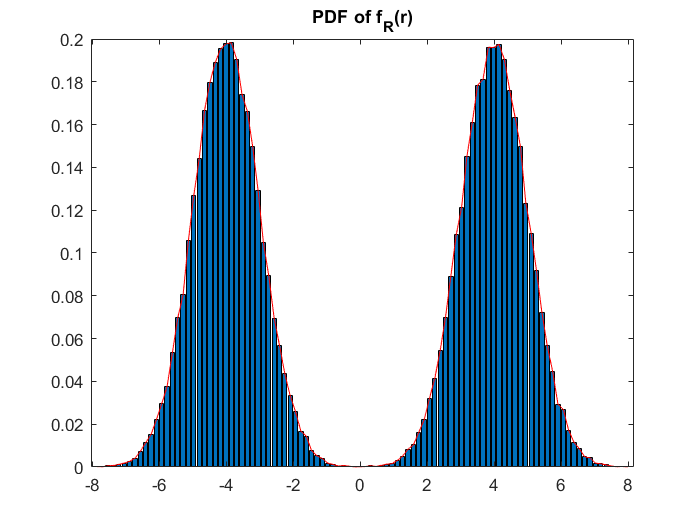

%5d
%plotting the pdf of f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF of f_R(r)");

FUNCTIONS

function Plot(L,sequence,plot_title,x_label,y_label)
stairs((1:L),sequence) %getting the plot
title(plot_title)
xlabel(x_label)
ylabel(y_label)
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%function to generate the histogram of the received sequence
function [histo,bin] = myhisto(seq,nbins)
max_seq = max(seq);
min_seq = min(seq);
gap = (max_seq-min_seq)/nbins;
histo = zeros(1,nbins);
for cnt = 1:nbins
    for len = 1:length(seq)
        if seq(len)>=(min_seq+(cnt-1)*gap) && seq(len)<=(min_seq+cnt*gap)
            histo(cnt) = histo(cnt) + 1;
        end
    end
end
bin = (min_seq+(gap/2)):gap:(max_seq-(gap/2));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%function for conditional PDFs
function [R_pdf,R_bins] = fRS(R,S,A)
    rsa = []; %R if S is A
    ind = 1;
    for cnt = 1:length(R)
        if S(cnt) == A
            rsa(ind) = R(cnt);
            ind = ind + 1;
        end
    end
    Max = max(rsa);
    Min = min(rsa);
    gap = (Max-Min)/100;
    [R_pdf,R_bins]=myhisto(rsa,100);
    R_pdf = R_pdf/((ind-1)*gap);
end
